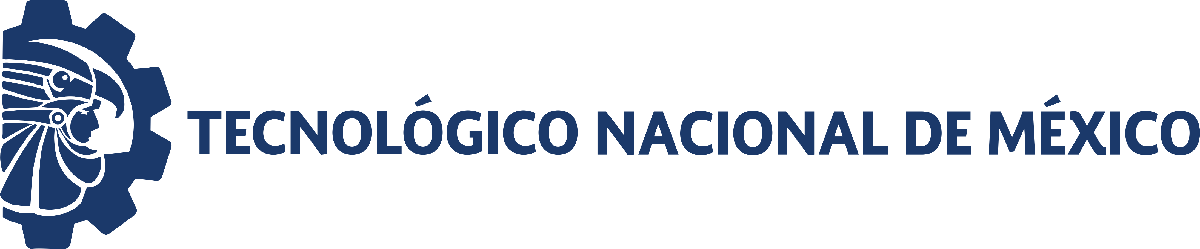                                 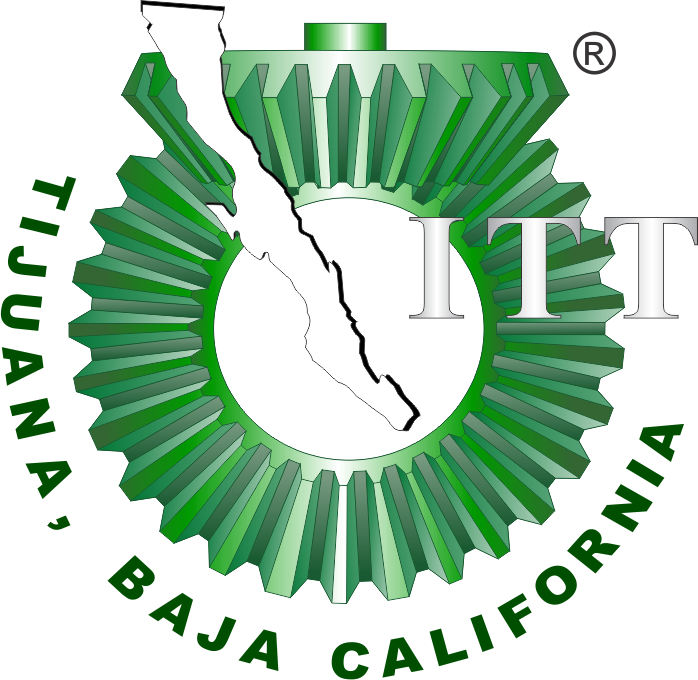

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

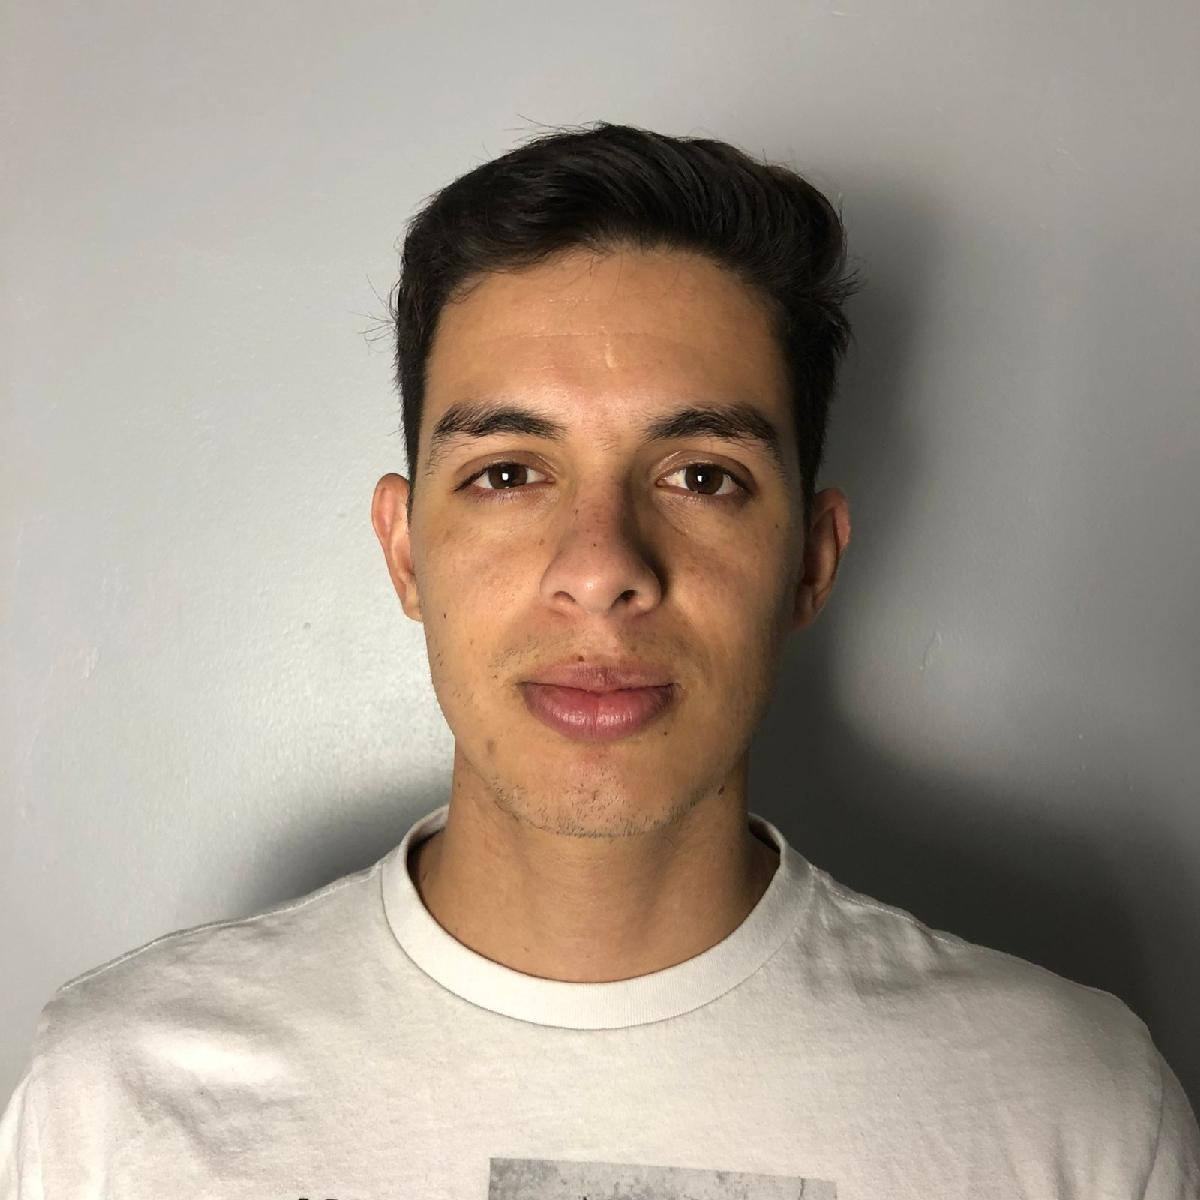

Nombre del alumno: Chizek Espinoza Josue

Número de control: 22212382

Correo institucional: l22212382**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SistemaA';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Respuesta al escalón

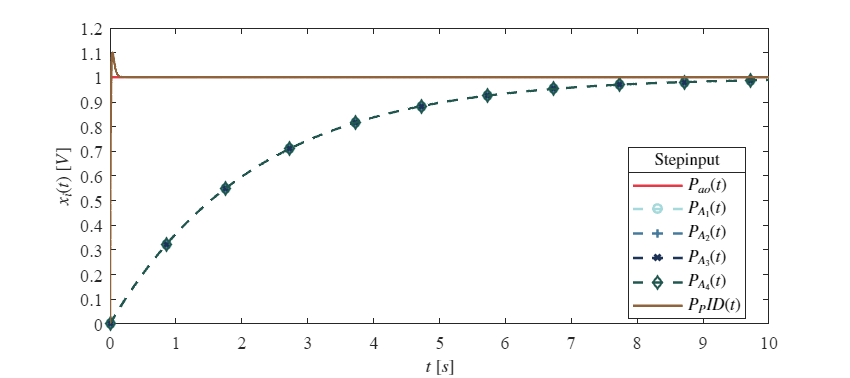

Signal = 'Step';
set_param('SistemaA/S1','sw','1');
set_param('SistemaA/Pao(t)','sw','1');
X1 = sim(file,parameters);
plotsignals(X1.t,X1.Pao,X1.PA1,X1.PA2,X1.PA3,X1.PA4,X1.PID,Signal)

## Respuesta al impulso

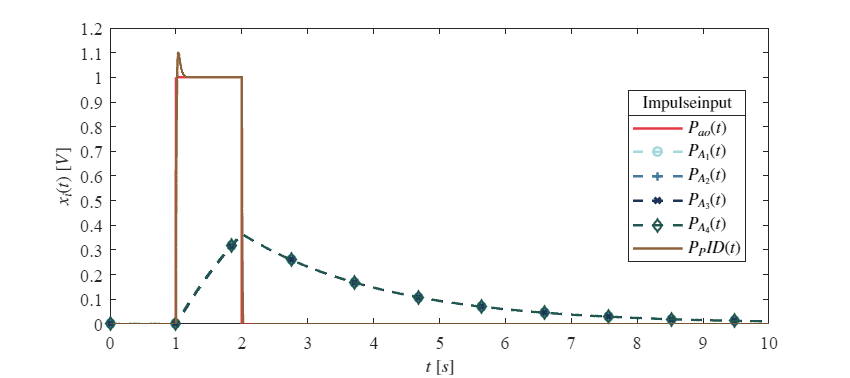

Signal = 'Impulse';
set_param('SistemaA/S1','sw','0');
set_param('SistemaA/Pao(t)','sw','1');
X2 = sim(file,parameters);
plotsignals(X2.t,X2.Pao,X2.PA1,X2.PA2,X2.PA3,X2.PA4,X2.PID,Signal)

## Respuesta a la rampa

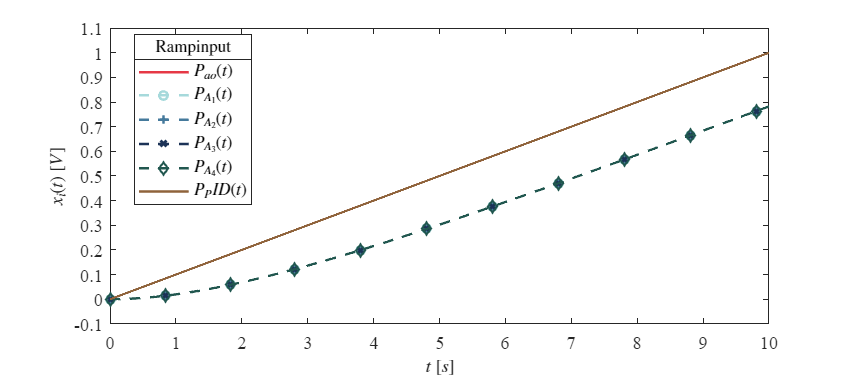

Signal = 'Ramp';
set_param('SistemaA/S2','sw','1');
set_param('SistemaA/Pao(t)','sw','0');
X3 = sim(file,parameters);
plotsignals(X3.t,X3.Pao,X3.PA1,X3.PA2,X3.PA3,X3.PA4,X3.PID,Signal)

## Respuesta a la función sinusoidal

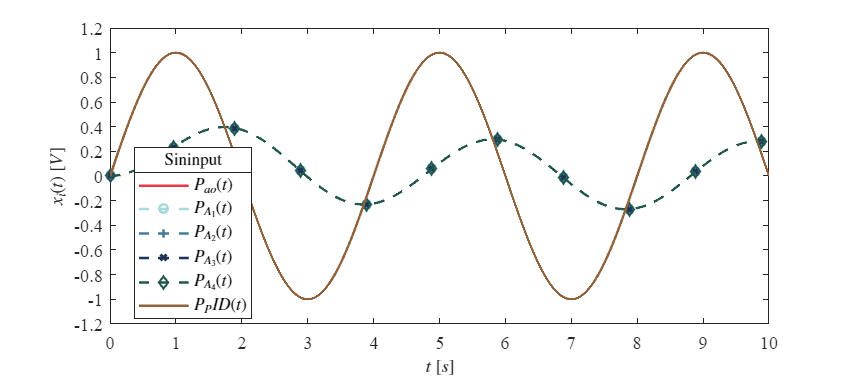

Signal = 'Sin';
set_param('SistemaA/S2','sw','0');
set_param('SistemaA/Pao(t)','sw','0');
X4 = sim(file,parameters);
plotsignals(X4.t,X4.Pao,X4.PA1,X4.PA2,X4.PA3,X4.PA4,X4.PID,Signal)

## Función: Respuesta a las señáles

function plotsignals(t,Pao,PA1,PA2,PA3,PA4,PID,Signal)
    set(figure(),'Color','w')
    set(gcf, 'units','centimeters', 'position', [1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on;grid off;box on;
    mycolors = [0.90,0.22,0.27;
                0.65,0.85,0.86;
                0.27,0.48,0.61;
                0.11,0.20,0.34;
                0.13,0.34,0.31;
                0.56,0.39,0.23];
    colororder(mycolors)
    
 
   P = plot(t,Pao,'-',t,PA1,'--o',t,PA2,'--+',t,PA3,'--x',t,PA4,'--d', t,PID,...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
   set(p(6))
    L = legend('$P_{ao}(t)$','$P_{A_1}(t)$','$P_{A_2}(t)$','$P_{A_3}(t)$','$P_{A_4}(t)$', '$P_PID(t)$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','Best','Box','On');
    title(L,[Signal,'input'],"FontSize",10)

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

       xlim([0,10]); xticks(0:1:10);
    if Signal == "Step" || Signal == "Impulse" 
        ylim([0,1.2]); yticks(0:0.1:1.2);

    elseif Signal == "Ramp"
        ylim([-0.1,1.1]); yticks(-0.1:0.1:1.1);
    elseif Signal == "Sin"
        ylim([-1.2,1.2]); yticks(-1.2:0.2:2);
    end
        
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','vector')
end